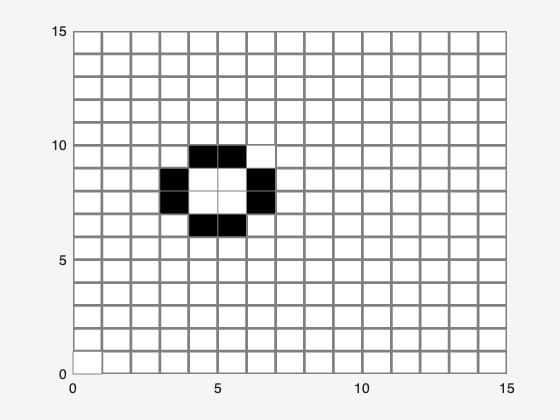




clear all; clc; close all
m = 15; %number of rows of cells
n = 15; %number of columns of cells
figure %open figure window
drawCells(m,n) %Draw cells (all dead, i.e., white)
[R,C] = inputLiveCells(m,n); %Populate R and C arrays with subscripts of selected live cells
% and color live cells black in the figure window
% %Evolve pattern indefinitely
x = evolveState(R,C,m,n); %get pattern after the first tick
[Rnew, Cnew] = x{:};
while ~isequal([R; C],[Rnew; Cnew]) %as long as pattern is changing following a tick
R = Rnew; C = Cnew; %pass updated information through
x = evolveState(R,C,m,n); %obtain new pattern after one tick
[Rnew, Cnew] = x{:};
pause(0.3)
end

% title('Still Life')

%We got a fix the grid lines color are disappearing after each while loop.
